
gymnastSYS.m = 5*[0.1564;0.23764;0.1564];
gymnastSYS.l = 5*[0.254;0.254;0.254];
% gymnastSYS.l = lengths(1,:)';
gymnastSYS.c = gymnastSYS.l.*0.1;
% gymnastSYS.c = COM_vec(28,:)';
gymnastSYS.dt = dt;

alpha = pi/4;
beta = pi/6;
gamma = pi/4;

n = 50; % number of points in trajectory

archRegion = 2*pi - [beta;beta+gamma];
hollowRegion = pi + [beta+gamma;beta];

gymnastSYS.alpha = alpha;
gymnastSYS.beta = beta;
gymnastSYS.gamma = gamma;
gymnastSYS.archRegion = archRegion;
gymnastSYS.hollowRegion = hollowRegion;




% x = [pi/6 0 0 0 0 0;
% %     0 0 0 0 0 0
%     archRegion(1) 0 0 0 0 0;
%     archRegion(2) alpha alpha 0 0 0;
%     hollowRegion(1) 0 0 0 0 0;
%     hollowRegion(2) -alpha -alpha 0 0 0;
%     -5*pi/4 0 0 0 0 0];

x = [pi/6 pi/6 pi/6 0 0 0]

x =     0.5236    0.5236    0.5236         0         0         0


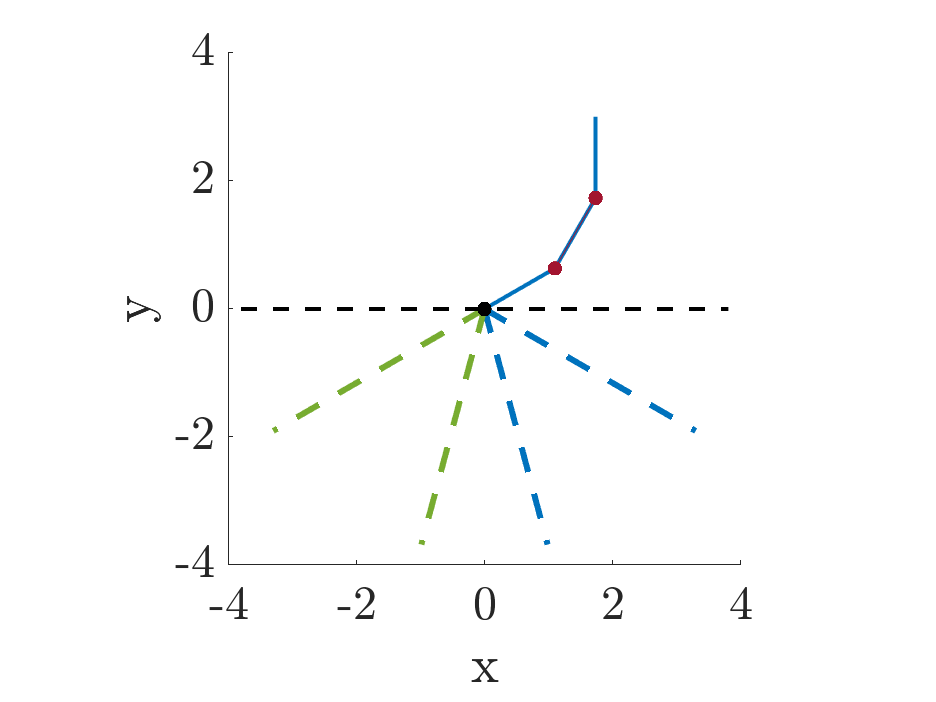


% Define parameters
m = gymnastSYS.m;
l = gymnastSYS.l;
c = gymnastSYS.c;



% Create trace of trajectory and particle object
h = figure();
hold on;
manipulator = [];
endeffector = [];
joints = [];
com = [];

% Set up axes
axis equal
axis([-4 4 -4 4])
xlabel('x')
ylabel('y')

% draw
base = [0;0];
L = sum(l);

xRegionArch = [base(1) L*cos(gymnastSYS.archRegion(1));...
               base(1) L*cos(gymnastSYS.archRegion(2))];
%                L*cos(gymnastSYS.archRegion(1)) L*cos(gymnastSYS.archRegion(2))];
yRegionArch = [base(1) L*sin(gymnastSYS.archRegion(1));...
               base(1) L*sin(gymnastSYS.archRegion(2))];
%                L*sin(gymnastSYS.archRegion(1)) L*sin(gymnastSYS.archRegion(2))];

arch = line(xRegionArch', yRegionArch', 'Color', [0 0.4470 0.7410],'LineStyle','--','linewidth',3);


xRegionHollow = [base(1) L*cos(gymnastSYS.hollowRegion(1));...
               base(1) L*cos(gymnastSYS.hollowRegion(2))];
%                L*cos(gymnastSYS.hollowRegion(1)) L*cos(gymnastSYS.hollowRegion(2))];
yRegionHollow = [base(1) L*sin(gymnastSYS.hollowRegion(1));...
               base(1) L*sin(gymnastSYS.hollowRegion(2))];
%                L*sin(gymnastSYS.hollowRegion(1)) L*sin(gymnastSYS.hollowRegion(2))];

arch = line(xRegionHollow', yRegionHollow', 'Color', [0.4660 0.6740 0.1880],'LineStyle','--','linewidth',3);


for ii = 1:length(x(:,1))
    a = tic;
    
    set(gcf,'DoubleBuffer','on');
    
    q1 = x(ii,1);
    q2 = x(ii,2);
    q3 = x(ii,3);
    comX = (m(1)*c(1)*cos(q1) + m(2)*(l(1)*cos(q1) + c(2)*cos(q1+q2)) + m(3)*(l(1)*cos(q1) + l(2)*cos(q1+q2) + c(3)*cos(q1+q2+q3)))/sum(m);
    comY = (m(1)*c(1)*sin(q1) + m(2)*(l(1)*sin(q1) + c(2)*sin(q1+q2)) + m(3)*(l(1)*sin(q1) + l(2)*sin(q1+q2) + c(3)*sin(q1+q2+q3)))/sum(m);
    joint1 = [l(1)*cos(q1);l(1)*sin(q1)];
    joint2 = [l(1)*cos(q1) + l(2)*cos(q1+q2);l(1)*sin(q1) + l(2)*sin(q1+q2)]; 
    joint3 = [l(1)*cos(q1) + l(2)*cos(q1+q2) + l(3)*cos(q1+q2+q3);l(1)*sin(q1) + l(2)*sin(q1+q2) + l(3)*sin(q1+q2+q3)];
    line([-sum(l) sum(l)],[0 0], 'Color', [0;0;0],'LineStyle','--','linewidth',2);
    line([base(1), joint1(1), joint2(1), joint3(1)], [base(2), joint1(2), joint2(2), joint3(2)], 'Color', [0 0.4470 0.7410],'LineStyle','-','linewidth',2);
    line([joint1(1), joint2(1)], [joint1(2), joint2(2)],'Color',[0.6350 0.0780 0.1840],'Marker','.', 'MarkerSize', 20);
    line(base(1), base(2), 'Color', [0;0;0],'Marker','.', 'MarkerSize', 20);
    
    
    drawnow limitrate
end